# BUCK CCM vs. DCM

## Device values

clear 
clc
R = 20                  % Load resistances [ohm]

R = 20

fsw = 200e3             % switching frequency

fsw = 200000

T = 1/fsw;
Lvec = [22e-6 470e-6]   % Buck inductor [H]

Lvec = 	1.0e+-3 *

    0.0220    0.4700


%erste Spule DCM, zweite CCM


## Conversion ratio for the Buck


$$k=\frac{2\cdot L}{R\cdot T}$$



$$k_{crit}=(1-D)$$


Buck operates in DCM for $k < k_{crit}$

Conversion ratio is

- DCM: $M(D) = \frac{V_C}{V_{in}} = \frac{2}{1 + \sqrt{1 + \frac{4 K}{D^2}}}$

- CCM: $M(D) = D$

Dvec = 0.1:0.01:0.9; % duty cycle vector

legendstr = {['a']};
i = 1;
for L = Lvec
    k = (2*L)/(R*T);    
    legendstr{i} = ['L = ' num2str(L), ', k = ' num2str(k)];
    disp(legendstr{i})
    j = 1;
    for D = Dvec
        if (k<(1-D))
            M(i,j)= (2 ./ (1 + sqrt(1 + 4*k./D.^2) ));
        else
            M(i,j) = D;
        end
        j = j + 1;
    end
    i = i+1;
end

L = 2.2e-05, k = 0.44
L = 0.00047, k = 9.4


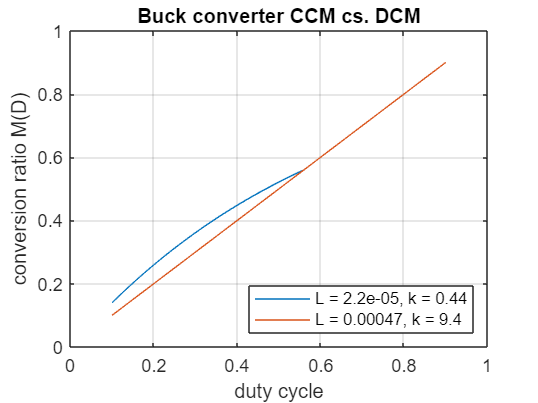


plot(Dvec,M)
grid on
title('Buck converter CCM cs. DCM')
xlabel('duty cycle')
ylabel('conversion ratio M(D)')
legend(legendstr,location = 'SouthEast')

### Design CCM and DCM Buck converters based on the results above

- Conversion ratio M = 0.5

- Vin = 400V

- Vout = 200V


$$M(D) = \frac{V_C}{V_{in}} = \frac{2}{1 + \sqrt{1 + \frac{4 K}{D^2}}}$$



$$k=\frac{2\cdot L}{R\cdot T}$$


% Todo
syms Msym Ksym Dsym S1 S2

kDCM = 2*Lvec(1)/(R*T)

kDCM = 0.4400



eqn = 2 / (1 + sqrt(1 + ( 4*Ksym / (Dsym^2)) ) ) == Msym

$$eqn = \frac{2}{\sqrt{\frac{4\,\mathrm{Ksym}}{{\mathrm{Dsym}}^{2}}+1}+1}=\mathrm{Msym}$$


S1 = solve(eqn, Ksym, 'ReturnConditions', true);
S2 = solve(eqn, Dsym, 'ReturnConditions', true);

D1 = sqrt(4*kDCM/((2/0.5-1)^2-1) )

D1 = 0.4690